Аппроксимировать функцию x=x(t) в пространстве L2(−1;1) двумя способами:

A. При помощи ортогональной тригонометрической системы.

B. При помощи ортогональных многочленов Лежандра.

syms k

**Апроксимация функции ln(1+x) при помощи тригонометрической системы**

x1=@(t) 1-abs(t);
n=7;
a=zeros(1,7);
b=zeros(1,7);
a0=(1/sqrt(2))*integral( x1, -1, 1 );
disp(["а0 для функции 1-|t|",a0]);

    "а0 для функции 1-|t|"    "0.70711"



Подсчета a_k и b_k

for k = 1:n
    a(k) = integral(@(t) x1(t).*cos(k*pi*t), -1, 1);
    b(k) = integral(@(t) x1(t).*sin(k*pi*t), -1, 1);
end
tt=linspace(-1,1,100);
orig=x1(tt);

Частичная сумма ряда Фурье

Trig = a0/sqrt(2) * ones(size(tt));
for k=1:n
    Trig = Trig + a(k)*cos(k*pi*tt) + b(k)*sin(k*pi*tt);
end


Расстояние между изначальной функцией и частичной суммой ее ряда Фурье:

integr = @(t) (x1(t) - (a0/sqrt(2) + sum(a' .* cos((1:n)' * pi * t), 1) + sum(b' .* sin((1:n)' * pi * t), 1))).^2;
norma = sqrt(integral(integr, -1, 1));
disp(["расстояние между функцией и частичной суммой ряда:", norma]);

    "расстояние между функцией и частичной суммой ряда:"    "0.0072029"



**Апроксимация функции 1 - |**`t|`** при помощи ортогональных полиномов Лежандра.**

Переводим функцию в символьный вид и инциализируем массивы

syms t                                              
f  = 1 - abs(t);                                  
c = sym( zeros(1,n+1) );
P = sym( zeros(1,n+1) );

Строим полином и частичную сумму ряда

for k = 0:n
    P(k+1) = legendreP(k, t);
    c(k+1) = (2*k+1)/2 * int( f*P(k+1), t, -1, 1 );
end

Leg_s = simplify( sum( c .* P ) );
Leg = double( subs(Leg_s, t, tt) );

Расстояние между изначальной функцией и частичной суммой ряда:

vec   = 0:n;
vic = sum( c.^2 .* ( 2./(2*vec+1) ) );
normaL   = sqrt( int( f^2, t, -1, 1 ) - vic );
fprintf('Расстояние между функцией и частичной суммоей ряда %.4f\n', double(normaL));

Расстояние между функцией и частичной суммоей ряда 0.0319


По результатам (0,0319 и 0.0072) видно, что тригонометрическая система дает более точную апроксимацию функции

Графики

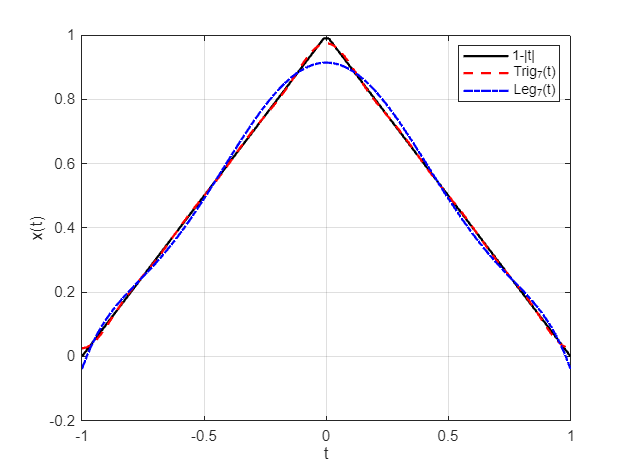

plot(tt, orig, 'k-',  'LineWidth', 1.5);  
hold on
plot(tt, Trig, 'r--', 'LineWidth', 1.5);   
plot(tt, Leg,  'b-.', 'LineWidth', 1.5);   
hold off

legend('1-|t|', 'Trig_7(t)', 'Leg_7(t)', 'Location', 'best');
xlabel('t');
ylabel('x(t)');
grid on

Графики подтверждают то, что тригонометрическая система дает более точную апроксимацию.